**%%Create datastores** 

imds = imageDatastore('dataset', ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain,imdsVal] = splitEachLabel(imds,0.8,'randomized');


**%%Define Augmentation and Preprocessing**

inputSize = [227 227 3];
augTrain = augmentedImageDatastore(inputSize, imdsTrain, ...
    'DataAugmentation', imageDataAugmenter( ...
    'RandRotation',[-20 20], ...
    'RandXTranslation',[-30 30], ...
    'RandYTranslation',[-30 30], ...
    'RandXScale',[0.9 1.1], ...
    'RandYScale',[0.9 1.1], ...
    'RandXReflection',true));

augVal = augmentedImageDatastore(inputSize, imdsVal);


**%%Build a CNN Architecture**

layers = [
    imageInputLayer(inputSize)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,256,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,512,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,512,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(512)
    dropoutLayer(0.5)
    fullyConnectedLayer(numel(unique(imds.Labels)))
    softmaxLayer
    classificationLayer];

**%%Test**

disp(layers(end-2))     % your final FC layer

  FullyConnectedLayer with properties:

          Name: ''

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 6

   Learnable Parameters
       Weights: []
          Bias: []

Use properties method to see a list of all properties.



disp(categories(imdsTrain.Labels))

    {'Ahegao'  }
    {'Angry'   }
    {'Happy'   }
    {'Neutral' }
    {'Sad'     }
    {'Surprise'}



**%%Define training options**

options = trainingOptions('adam', ...
  'InitialLearnRate',1e-4, ...
  'MaxEpochs',100, ...
  'MiniBatchSize',8, ...
  'Shuffle','every-epoch', ...
  'ValidationData',augVal, ...
  'ValidationFrequency',floor(numel(imdsTrain.Files)/8), ...
  'ValidationPatience',10, ...
  'Plots','training-progress', ...
  'ExecutionEnvironment','gpu');

**%%Train the network**

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |       50.00% |       16.73% |       2.8815 |       2.7077 |      1.0000e-04 |
|       1 |          50 |       00:00:18 |       25.00% |              |       4.2307 |              |      1.0000e-04 |
|       1 |         100 |       00:00:21 |       12.50% |              |       5.3845 |              |      1.0000e-04 |
|       1 |         150 |       00:00:25 |       25.00% |              |       3.8737 |              |      1.0000

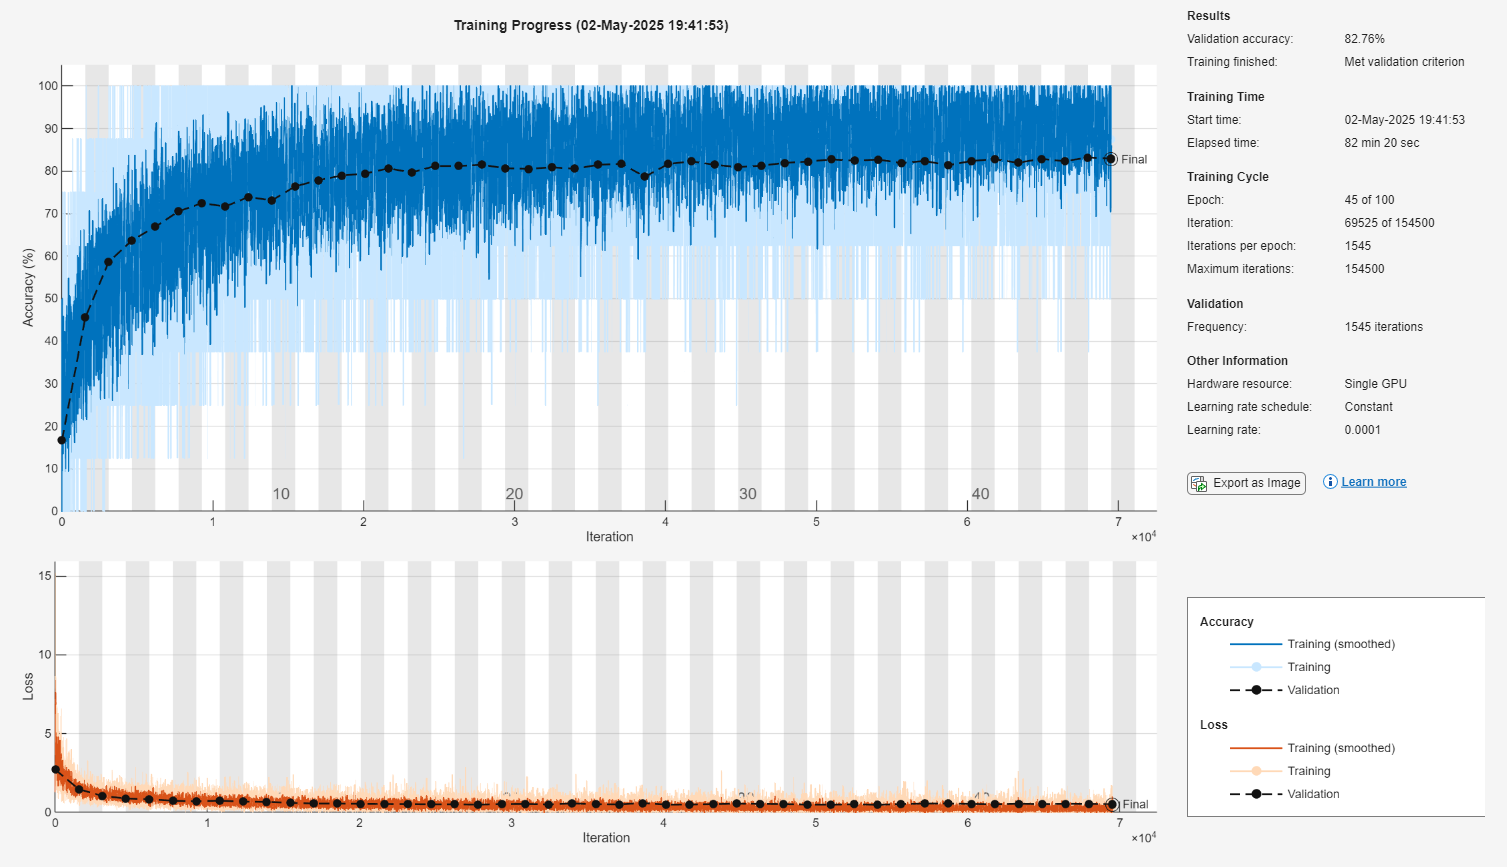

[emotionNet10, trainInfo10] = trainNetwork(augTrain, layers, options);

**%%Evaluate on Validation Set**

% Classify validation images:
[YPred, scores] = classify(emotionNet10, augVal);
YTrue = imdsVal.Labels;

% Compute accuracy:
accuracy = mean(YPred == YTrue);
disp("Validation accuracy: " + accuracy*100 + "%");

Validation accuracy: 82.7564%


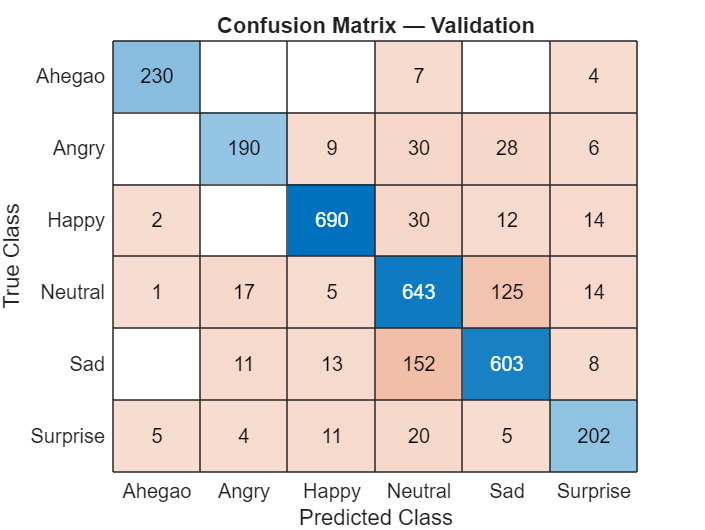


% Confusion matrix:
figure;
confusionchart(YTrue, YPred);
title('Confusion Matrix — Validation');

**%%Save Your Model**

save('emotionCNN10.mat','emotionNet10','trainInfo10');
